x est la valeur interpolée linéairement à l'intérieur du moteur d'interpolation MIEM (interpolation linéaires sur valeurs normalisées)

Les différentes sorties y sont les valeurs mises à l'échelle (avec y1 et y2 les min et max) et déformées selon différentes courbes

clear all; close all; clc;

minX = 0;
maxX = 1;
deltaX = maxX - minX;
inputX = minX : (deltaX / 1000) : maxX;
centerX = (maxX + minX) / 2;

normalizedX = ((inputX - minX) / deltaX);

% min and max values
minY = 100;
maxY = 1000;
% valeurs utiles pour l'implémentation C++ optimisée
centerY = (maxY + minY)/2;
deltaY = maxY - minY;

% fonction implémentées dans BasicInterpolationCurve.hpp
y_linear_interp = minY + normalizedX * deltaY;

[a, b, c] = LogInterpolationCoeffs(minY, maxY);

nombreDecades = 1

centerYlog = 316.2278

delta_eq2 = 1.7706e+11

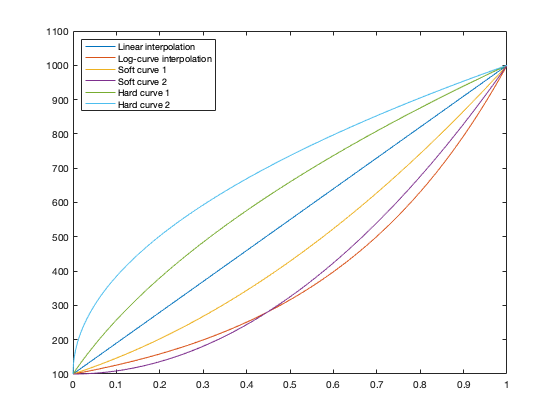

y_log_interp = a .* exp(b .* normalizedX) + c;

% alpha = taux de linéarité des courbes soft et hard contrôlables
alpha_s = 0.3;
alpha_h = 0.1;

a_soft = (deltaY * (1.0-alpha_s)*(1.0-alpha_s) ) / (deltaX * deltaX * (1.0 - alpha_s*alpha_s) );
b_soft = (2.0 * alpha_s * (1.0 - alpha_s) * deltaY ) / ( (1.0 - alpha_s*alpha_s) * deltaX );
y_soft1 = a_soft * (inputX - minX).*(inputX - minX) + b_soft * (inputX - minX) + minY;

m_soft = (deltaY / (deltaX * deltaX));
y_soft2 = m_soft * (inputX - minX).*(inputX - minX) + minY;

a_hard = (deltaY / (1.0 - sqrt(alpha_h)));
b_hard = ((1.0 - alpha_h) / deltaX);
c_hard = (minY - ((deltaY*sqrt(alpha_h)) / (1.0 - sqrt(alpha_h))));
y_hard1 = a_hard * sqrt(alpha_h + b_hard*(inputX - minX)) + c_hard;

m_hard = (deltaY / sqrt(deltaX));
y_hard2 = m_hard * sqrt(inputX - minX) + minY;

interpFig = figure;
plot(inputX, y_linear_interp);
hold on;
plot(inputX, y_log_interp);
plot(inputX, y_soft1);
plot(inputX, y_soft2);
plot(inputX, y_hard1);
plot(inputX, y_hard2);
legend('Linear interpolation', 'Log-curve interpolation', 'Soft curve 1', 'Soft curve 2', 'Hard curve 1', 'Hard curve 2', 'Location', 'northwest');